# Wykres słupkowy

[Odnośnik do dokumentacji języka Matlab](https://www.mathworks.com/help/matlab/ref/bar.html).

Podstawowe użycie tego typu wykresu wymaga jedynie wartości na osi pionowej. W takim wypadku wartościami zaznaczonymi na osi poziomej będą kolejne liczby.

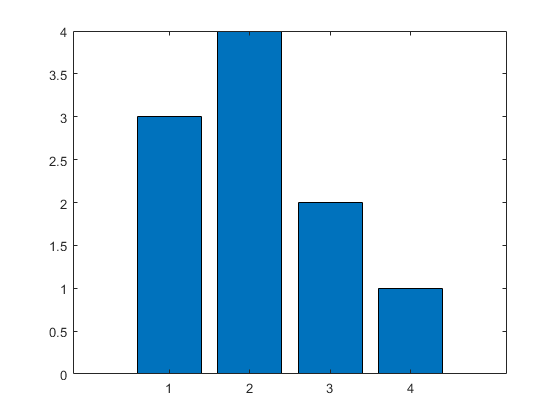

y = [3,4,2,1];
bar(y)

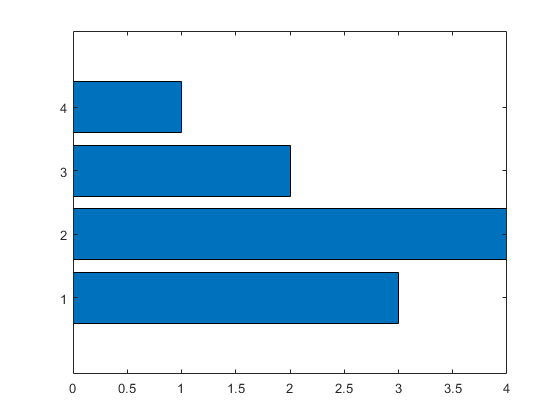

y = [3,4,2,1];
barh(y)

W przypadku przekazania wektora wartości x, zostaną one odznaczone z zachowaniem proporcji.

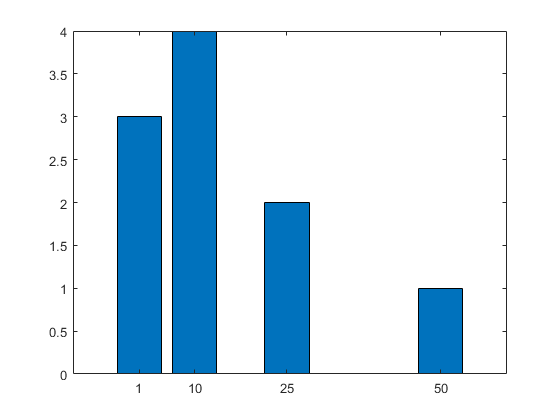

x = [1, 10, 25, 50];
y = [3, 4, 2, 1];
bar(x,y)

Możliwe jest przekazanie różnych serii danych. W takim wypadku dane odpowiadające konkretnej wartości x, umieszcza się w wierszu.

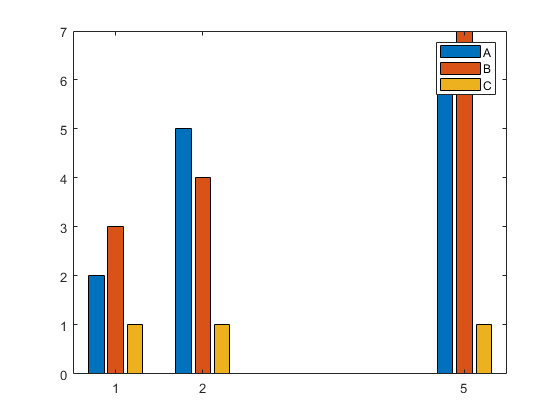

X = [1,2,5];
  %  A B C
Y = [2,3,1;  % X(1) = 1
     5,4,1;  % X(2) = 2
     6,7,1]; % X(3) = 5
bar(X,Y)
legend(["A","B","C"])

Użycie opcji 'stacked' sprawia, że wartości dla różnych kategorii są na siebie nakładane.

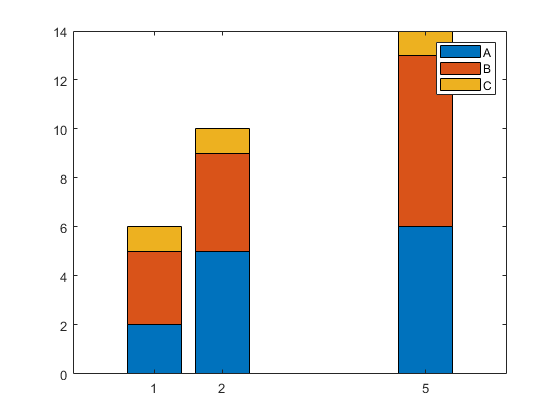

X = [1,2,5];
Y = [2,3,1;
     5,4,1;
     6,7,1];
bar(X,Y,'stacked')
legend(["A","B","C"])

Najłatwiejszym sposobem przypisania etykiet wartościom  jest użycie zmiennej typu kategorycznego. Jednak w takim wypadku odstępy między wartościami na osi x będą identyczne.

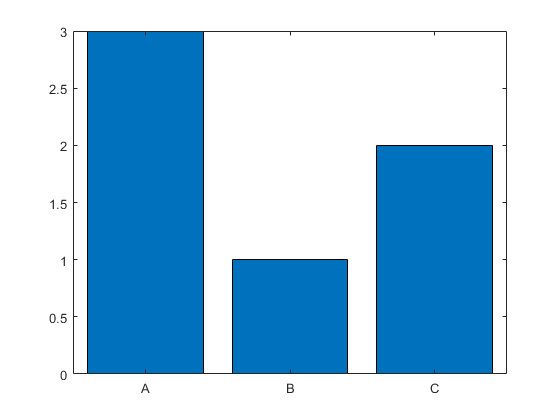

X = categorical({'A','B','C'});
X = reordercats(X,{'A','B','C'}); 
   % A  B  C
Y = [3, 1, 2];
bar(X,Y)

Aby zachować proporcje między wartościami na osi x, a mimo to wyświetlić etykiety zamiast wartości można użyć funkcji [xticklabels()](https://www.mathworks.com/help/matlab/ref/xticks.html).

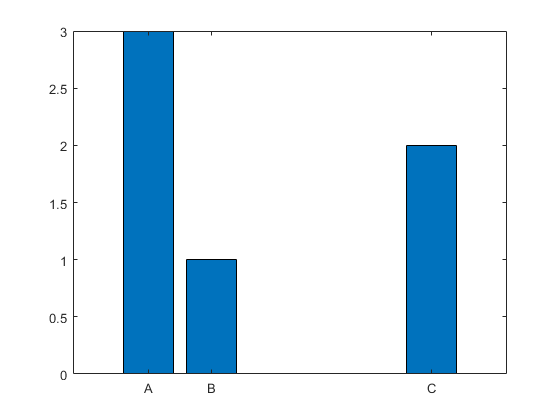

X = [1,3,10];
Y = [3, 1, 2];
bar(X,Y)
xticklabels({'A','B','C'})